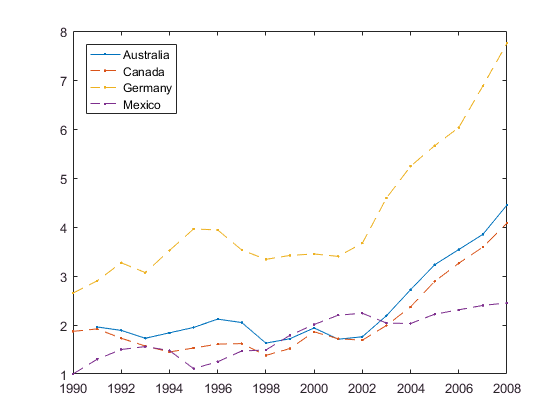

load gCosts.mat

gal2lit = 0.2642;

plot(Year, Australia, '.-')
hold on
plot(Year, Canada, '.--')
plot(Year, Germany, '.--')
plot(Year, Mexico, '.--')
hold off

legend(country, 'Location','northwest')

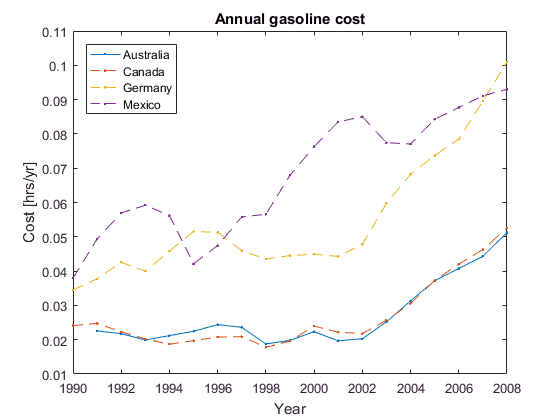


Australia = Australia * gal2lit / hourlyAus;
Canada = Canada * gal2lit / hourlyCan;
Germany = Germany * gal2lit / hourlyGer;
Mexico = Mexico * gal2lit / hourlyMex;

plot(Year, Australia, '.-')
hold on
plot(Year, Canada, '.--')
plot(Year, Germany, '.--')
plot(Year, Mexico, '.--')
hold off

title('Annual gasoline cost');
xlabel('Year');
ylabel('Cost [hrs/yr]');

legend(country, 'Location','northwest')

## Fluctuation between australia and canada

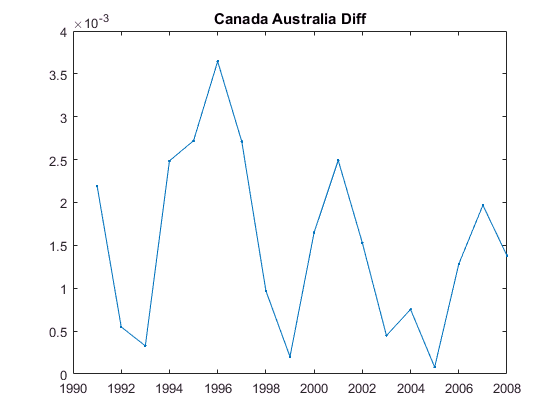

AuCaDiff = abs(Canada - Australia);

plot(Year, AuCaDiff, '.-')
hold on
title('Canada Australia Diff');
hold off

h = [1, 2, 3, 4]

h =      1     2     3     4

sin(h)

ans =     0.8415    0.9093    0.1411   -0.7568

## Statistical Functions

% Mean absolute value
avgDiff = mean (AuCaDiff, 'omitnan')

avgDiff = 0.0015

nanmean(AuCaDiff)

ans = 0.0015

## Get rid of the NaN

Australia(1) = Australia (2)

Australia =     0.0226
    0.0226
    0.0218
    0.0199
    0.0212
    0.0224
    0.0244
    0.0236
    0.0188
    0.0198

Australia(1) = Australia(end-1)

Australia =     0.0443
    0.0226
    0.0218
    0.0199
    0.0212
    0.0224
    0.0244
    0.0236
    0.0188
    0.0198


Aus90 = Australia(1)

Aus90 = 0.0443

## Years from 1990 to 2008

x = 1990:2008

x =         1990        1991        1992        1993        1994        1995        1996        1997        1998        1999        2000        2001        2002        2003        2004        2005        2006        2007        2008

eox = 1990:2:2008     % like an integral

eox =         1990        1992        1994        1996        1998        2000        2002        2004        2006        2008

partx = linspace(1990,2008,4)

partx =         1990        1996        2002        2008

L = length(partx)

L = 4

length(x)

ans = 19

## When was the biggest difference between Australia and Canada

AuCaDiff = abs(Canada - Australia);
[Big,Idx] = max (AuCaDiff);

AuCaDiff = Year(Idx);

% 1st, 4th , 7-9th year
Year([1, 4, 7:9])

ans =         1990
        1993
        1996
        1997
        1998

Year(7:9)

ans =         1996
        1997
        1998


Mex90s = Mexico(1:10);
Mex00s = Mexico(11:end);

d90s = mean(Mex90s)

d90s = 0.0530

d00s = mean(Mex00s)

d00s = 0.0839

% diff, discrete derivative
h = [1 2 3 7 17];
diff(h);

flux90s = mean(diff(Mex90s))

flux90s = 0.0033

flux00s = mean(diff(Mex00s))

flux00s = 0.0021

[MexicoSorted, MexicoIdx] = sort(Mexico)

MexicoSorted =     0.0380
    0.0421
    0.0474
    0.0493
    0.0558
    0.0562
    0.0566
    0.0569
    0.0592
    0.0679

MexicoIdx =      1
     6
     7
     2
     8
     5
     9
     3
     4
    10

SortedYears = Year(MexicoIdx)

SortedYears =         1990
        1995
        1996
        1991
        1997
        1994
        1998
        1992
        1993
        1999

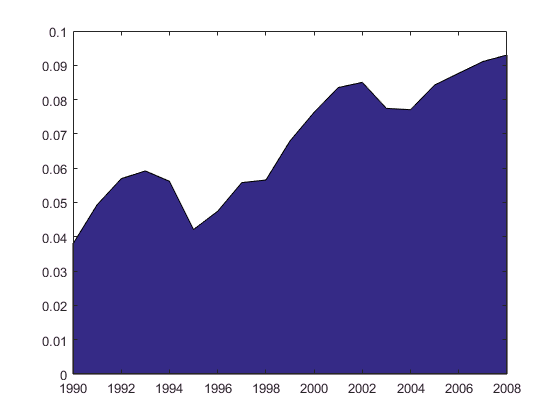


area(Year,Mexico)

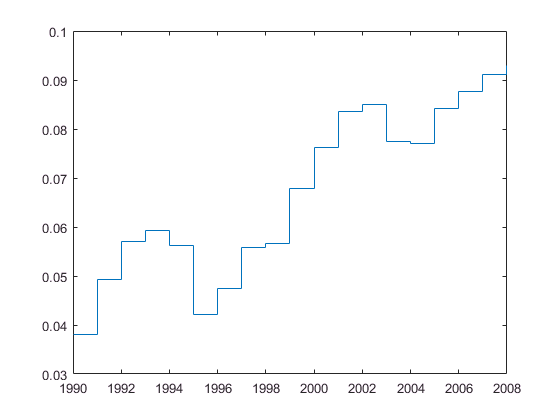

stairs(Year,Mexico)

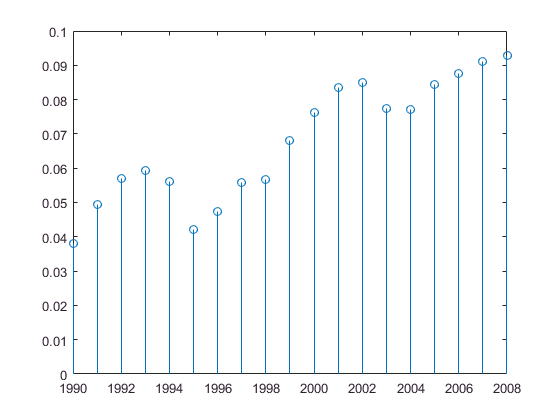

stem(Year,Mexico)

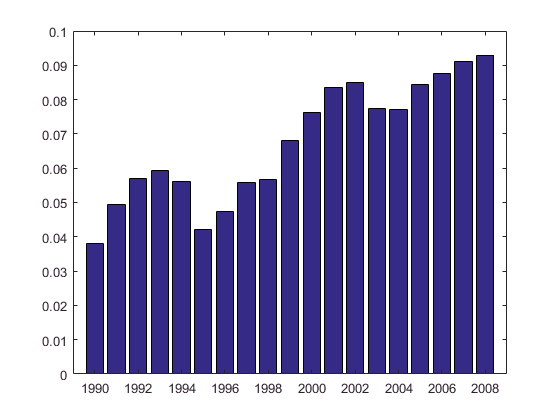

bar(Year,Mexico)

xlim([1989, 2009])


scatter(Australia, Canada)
AuLimits = xlim

AuLimits =     0.0150    0.0550

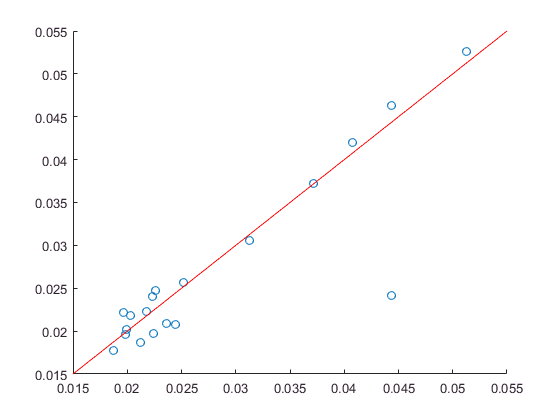

hold on
plot(AuLimits,AuLimits,'r')
hold off

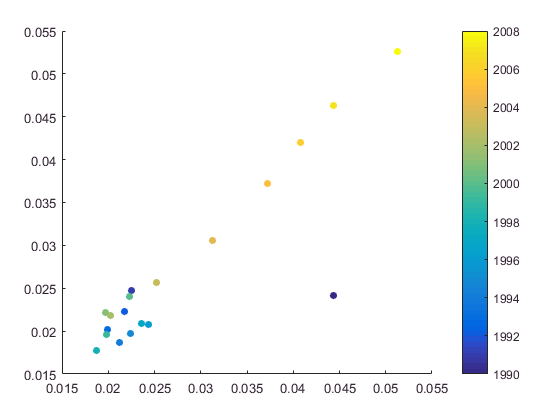


scatter(Australia, Canada, 30, Year, 'Filled')    % 30 is the size of the circles,Year acts as the weight
colorbar